# **PRÁCTICA FINAL**

# ** Interpolación de píxeles**

### ** FUNCIÓNES DEFINIDAS**

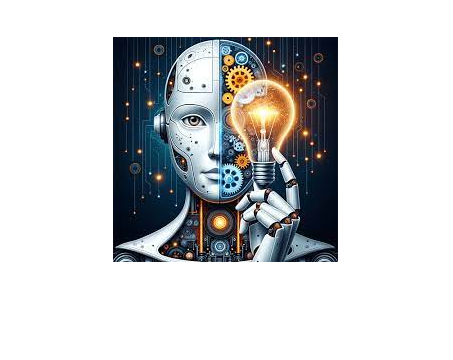

imagen_original = 'imagen.jpg';
imshow(imagen_original);

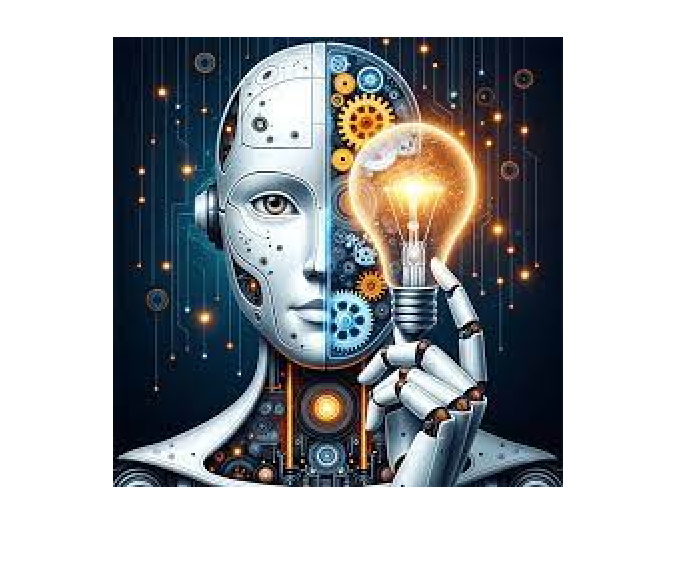

img_zoomed = ampliar_imagen('imagen.jpg', 2,1);
imshow(img_zoomed)

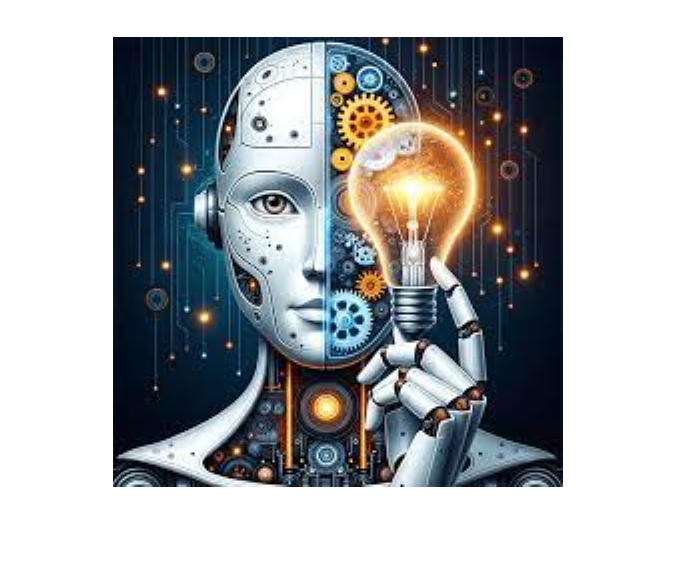


img_zoomed = ampliar_imagen('imagen.jpg', 2,2);
imshow(img_zoomed)

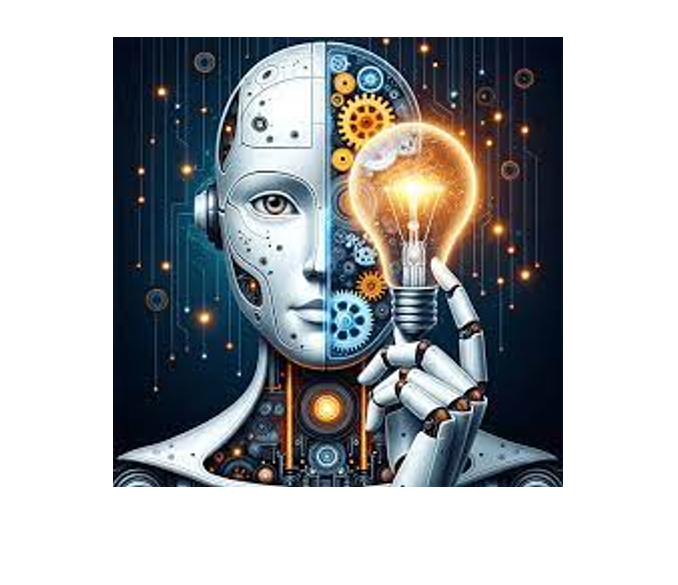

img_zoomed = ampliar_imagen('imagen.jpg', 2,3);
imshow(img_zoomed)

### COMPARACIÓN DE LOS MÉTODOS DE INTERPOLACIÓN

#### Imágenes originales

% definimos los vectores x e y
x = linspace(1, 50, 50); % 50 puntos entre 0 y 50
y = linspace(1, 50, 50); % 50 puntos entre 0 y 50

[X, Y] = meshgrid(x, y); % creamos una malla de coordenadas

% definimos y calculamos las funciones
f = sin(2*X) .* (X.^2 - X.*Y + Y.^2)

f = 1.0e+03 *

    0.0009   -0.0023   -0.0020    0.0129   -0.0114   -0.0166    0.0426   -0.0164   -0.0548    0.0831   -0.0010   -0.1204    0.1197    0.0496   -0.2085    0.1329    0.1444   -0.3045    0.1017    0.2839   -0.3859    0.0082    0.4572   -0.4248   -0.1577    0.6423   -0.3928   -0.3948    0.8072   -0.2655   -0.6882    0.9136   -0.0281   -1.0084    0.9217    0.3201   -1.3132    0.7965    0.7622   -1.5515    0.5140    1.2633   -1.6687    0.0670    1.7710   -1.6143   -0.5305    2.2200   -1.3492   -1.2411
    0.0027   -0.0030   -0.0020    0.0119   -0.0103   -0.0150    0.0386   -0.0150   -0.0503    0.0767   -0.0009   -0.1123    0.1121    0.0466   -0.1966    0.1257    0.1370   -0.2896    0.0969    0.2712   -0.3694    0.0079    0.4392   -0.4087   -0.1519    0.6196   -0.3794   -0.3818    0.7814   -0.2573   -0.6675    0.8869   -0.0273   -0.9805    0.8969    0.3117   -1.2797    0.7767    0.7437   -1.5147    0.5021    1.2347   -1.6318    0.0656    1.7335   -1.5808   -0.5197    2.1757   -

g = sin(X.*Y)

g =     0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794    0.6570    0.9894    0.4121   -0.5440   -1.0000   -0.5366    0.4202    0.9906    0.6503   -0.2879   -0.9614   -0.7510    0.1499    0.9129    0.8367   -0.0089   -0.8462   -0.9056   -0.1324    0.7626    0.9564    0.2709   -0.6636   -0.9880   -0.4040    0.5514    0.9999    0.5291   -0.4282   -0.9918   -0.6435    0.2964    0.9638    0.7451   -0.1586   -0.9165   -0.8318    0.0177    0.8509    0.9018    0.1236   -0.7683   -0.9538   -0.2624
    0.9093   -0.7568   -0.2794    0.9894   -0.5440   -0.5366    0.9906   -0.2879   -0.7510    0.9129   -0.0089   -0.9056    0.7626    0.2709   -0.9880    0.5514    0.5291   -0.9918    0.2964    0.7451   -0.9165    0.0177    0.9018   -0.7683   -0.2624    0.9866   -0.5588   -0.5216    0.9929   -0.3048   -0.7392    0.9200   -0.0266   -0.8979    0.7739    0.2538   -0.9851    0.5661    0.5140   -0.9939    0.3132    0.7332   -0.9235    0.0354    0.8940   -0.7795   -0.2453    0.9836   -0.5734   -0

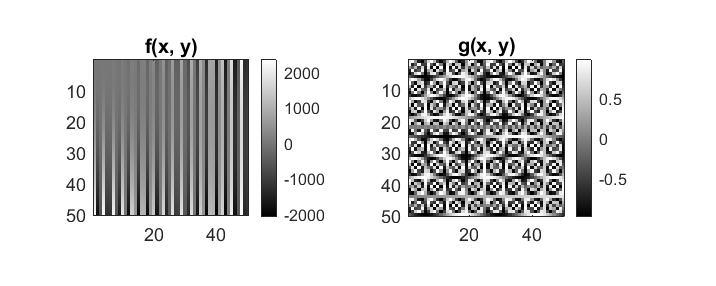

% visualizamos las funciones como imagenes en blanco y negro
figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
imagesc(x, y, f); % mostramos la imagen de f
axis image; 
colormap gray; 
colorbar;
title('f(x, y)');

subplot(1,2,2);
imagesc(x, y, g); % mostramos la imagen de g
axis image; 
colormap gray; 
colorbar;
title('g(x, y)');

Definimos las funciones f(x,y) y g(x,y) y los vectores x e y que emplearemos en las siguientes comprobaciones:

tam = 50; % tamaño de la matriz
z = 1;
x = linspace(0, tam, tam); % 50 puntos entre 0 y 50
y = linspace(0, tam, tam); % 50 puntos entre 0 y 50

[X, Y] = meshgrid(x, y); % creamos una malla de coordenadas

% definimos y calculamos las funciones
f = sin(2*X) .* (X.^2 - X.*Y + Y.^2);
g = sin(X.*Y);

#### Interpolación del Vecino más Cercano

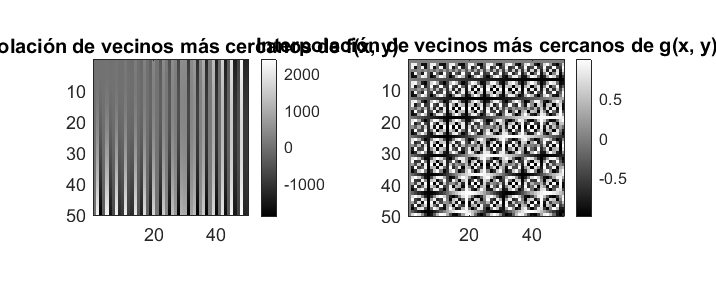

% definimos los vectores x e y
sol_f = zeros(z*tam, z*tam);
sol_g = zeros(z*tam, z*tam);

for i = 1:tam*z
    for j = 1:tam*z
        valor_f = interpolacion_vecinos([i,j], z, f);
        sol_f(i,j) = valor_f;
        valor_g = interpolacion_vecinos([i,j], z, g);
        sol_g(i,j) = valor_g;
    end
end

% visualizamos los resultados obtenidos
figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
imagesc(sol_f); % Cambiado para utilizar los resultados de interpolación directamente
axis image; 
colormap gray; 
colorbar;
title('Interpolación de vecinos más cercanos de f(x, y)');

subplot(1,2,2);
imagesc(sol_g); % Cambiado para utilizar los resultados de interpolación directamente
axis image; 
colormap gray; 
colorbar;
title('Interpolación de vecinos más cercanos de g(x, y)');

#### Interpolación Bilineal

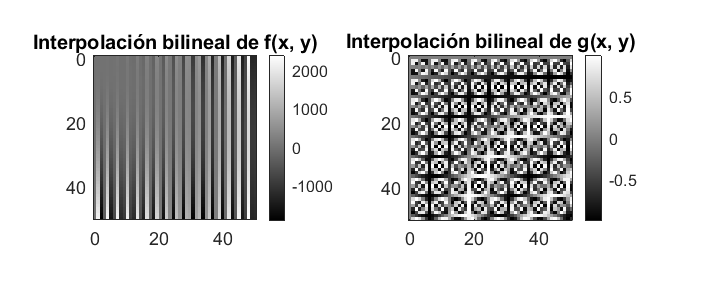

% obtenemos 4 puntos y aplicamos el metodo de interpolacion bilineal para f y g
sol_f = zeros(z*tam, z*tam);
sol_g = zeros(z*tam, z*tam);

for i=1:tam*z
    for j=1:tam*z
        puntos_f = obtencion4puntos([i,j], f, z);
        valor_f = interpolacion_bilineal(puntos_f, [i,j]);
        sol_f(i,j) = valor_f;
        puntos_g = obtencion4puntos([i,j], g, z);
        valor_g = interpolacion_bilineal(puntos_g, [i,j]);
        sol_g(i,j) = valor_g;
    end
end

% Visualización de los resultados
figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
imagesc(x, y, sol_f); % mostramos la imagen de f interpolada
axis image; 
colormap gray; 
colorbar;
title('Interpolación bilineal de f(x, y)');

subplot(1,2,2);
imagesc(x, y, sol_g); % mostramos la imagen de g interpolada
axis image; 
colormap gray; 
colorbar;
title('Interpolación bilineal de g(x, y)');

#### Interpolación Bicúbica

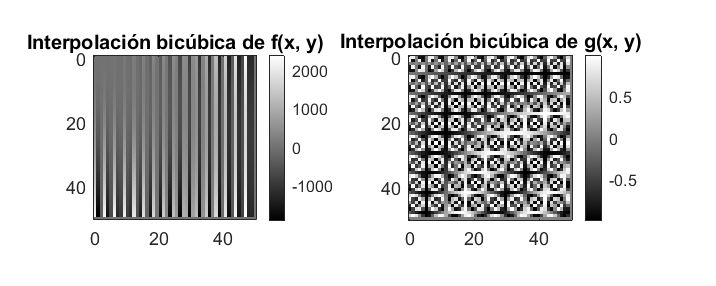

% calculamos las derivadas necesarias para la interpolación bicúbica
[Ix_f, Iy_f, Ixy_f] = calculo_derivadas(f);
[Ix_g, Iy_g, Ixy_g] = calculo_derivadas(g);

% preparamos las matrices de interpolación bicúbica para f y g
sol_f = zeros(z*tam, z*tam);
sol_g = zeros(z*tam, z*tam);

for i = 1:(z*tam)-1
    for j = 1:(z*tam)-1
        % escalamos i y j para que coincidan con las dimensiones
        % originales, de forma que no excedamos los limites de la matriz
        x_p = max(min(floor((i-1)/z) + 1, tam), 1);
        y_p = max(min(floor((j-1)/z) + 1, tam), 1);

        sol_f(i, j) = interpolacion_bicubica([x_p, y_p], f, Ix_f, Iy_f, Ixy_f);
        sol_g(i, j) = interpolacion_bicubica([x_p, y_p], g, Ix_g, Iy_g, Ixy_g);
    end
end

% visualizamos las imágenes interpoladas
figure('Position', [0, 0, 1000, 400]);
subplot(1,2,1);
imagesc(x, y, sol_f'); % mostramos la imagen de f interpolada
axis image; 
colormap gray; 
colorbar;
title('Interpolación bicúbica de f(x, y)');

subplot(1,2,2);
imagesc(x, y, sol_g); % mostramos la imagen de g interpolada
axis image; 
colormap gray; 
colorbar;
title('Interpolación bicúbica de g(x, y)');

### **INTERPOLACIÓN VECINOS MÁS CERCANOS**

function sol = interpolacion_vecinos(P, z, mat)
    x_o = floor((P(1)+(z-1))/z);
    y_o = floor((P(2)+(z-1))/z);
    sol = mat(x_o, y_o);
end 

### INTERPOLACIÓN BILINEAL 2D

Interpolamos un punto dados los 4 puntos más cercanos y el propio punto

Imagen de referencia

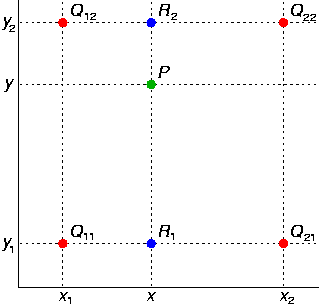

Demostración

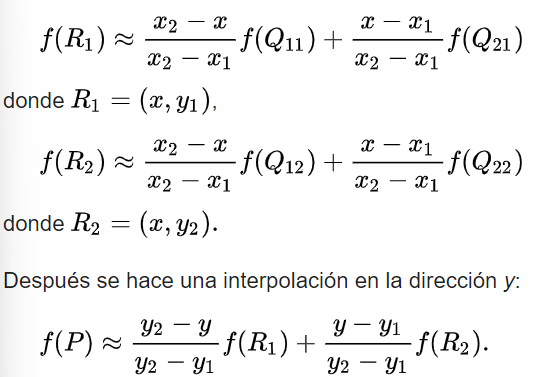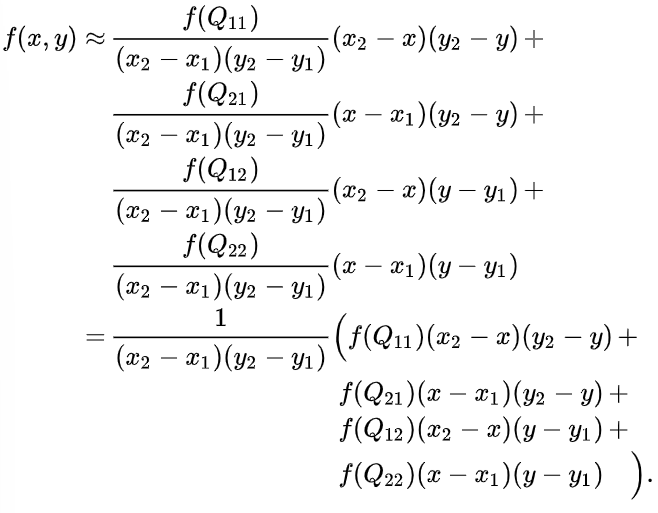

function sol = obtencion4puntos(P, mat, z)
    %dado un punto, una matriz y el tamaño a aumentar dicha matriz, calcula
    %los 4 píxeles conocidos más cercanos

    % Dimensiones de la imagen original
    [H, W, ~] = size(mat);

    % Inicialización de variables
    selected_i = 0;
    selected_j = 0;

    % Busco en i
    for i=1:z:H*z
        if i<=P(1) && i+z>=P(1) %voy de z en z porque son los puntos conocidos
            selected_i = i;
            break
        end 
    end 

    % Busco en j
    for j=1:z:W*z 
        if (j <= P(2)) && (j+z > P(2))
            selected_j = j;
            break
        end 
    end 

    %me devuelve el punto de arriba a la izquierda, ahora obtengo los 4
    %puntos restantes teniendo en cuneta donde está el punto objetivio
    Q11 = [selected_i, selected_j];
    Q22 = [0,0];
    Q12 = [0,0];
    Q21 = [0,0];
    f11 = mat((Q11(1)+(z-1))/z, (Q11(2)+(z-1))/z);
    f12 = 0;
    f21 = 0;
    f22 = 0;

    %contador para saber si existe el punto Q22, si llega a dos es que si
    cont = 0;
    
    %si existe un punto conocido a la derecha de P
    if selected_j+z <= z*W
        Q12 = [selected_i, selected_j+z];
        f12 = mat((Q12(1)+(z-1))/z, (Q12(2)+(z-1))/z);
        cont = cont+1;
    end

    %si existe un punto conocido debajo de P
    if selected_i+z <= z*H
        Q21 = [selected_i+z, selected_j];
        f21 = mat((Q21(1)+(z-1))/z, (Q21(2)+(z-1))/z);
        cont = cont+1;
    end 

    %conpruebo si existe Q22
    if cont == 2
        Q22 = [selected_i+z, selected_j+z];
        f22 = mat((Q22(1)+(z-1))/z, (Q22(2)+(z-1))/z);
    end 

    %obtengo el valor de los puntos
    sol = [f11, f12, f21, f22, Q11, Q12, Q22, Q21];

end 


function sol = interpolacion_bilineal(puntos, P)
    %obtenemos el valor de la funcion evaluada en cada Qij
    fq11 = puntos(1);
    fq12 = puntos(2);
    fq21 = puntos(3);
    fq22 = puntos(4);

    %obtenemos x1, x2, y1, y2
    x1 = puntos(5);
    x2 = puntos(11);
    y1 = puntos(6);
    y2 = puntos(8);
    x = P(1);
    y = P(2);

    %obtememos la estimación de f evaluada en P
    sol =(1/((x2-x1)*(y2-y1))) * ( (fq11*(x2-x)*(y2-y)) + (fq21*(x-x1)*(y2-y)) + (fq12*(x2-x)*(y-y1)) + (fq22*(x-x1)*(y-y1)) );
      
end 

### **INTERPOLACIÓN BICÚBICA**

function sol = interpolacion_bicubica(s, I, Ix, Iy, Ixy)
    [m, n] = size(I);

    x_p = s(1) + 1;
    y_p = s(2) + 1;
    
    % Encontramos los 4 puntos que rodean el punto x, y
    x1 = floor(x_p);
    y1 = floor(y_p);
    
    x2 = x1 + 1;
    y2 = y1 + 1;
    
    if x1 == n
      x1 = n - 1;
      x2 = n;
    end
    
    if y1 == m
      y1 = m - 1;
      y2 = m;
    end
   
    % Calculamos los coeficientes de interpolacion
    x = [I(y1,x1), I(y2,x1), Iy(y1,x1), Iy(y2,x1);
          I(y1,x2), I(y2,x2), Iy(y1,x2), Iy(y2,x2);
          Ix(y1,x1), Ix(y2,x1), Ixy(y1,x1), Ixy(y2,x1);
          Ix(y1,x2), Ix(y2,x2), Ixy(y1,x2), Ixy(y2,x2)];
          
    izquierda = [1, 0, 0, 0; 0, 0, 1, 0; -3, 3, -2, -1; 2, -2, 1, 1];
    derecha = [1, 0, -3, 2; 0, 0, 3, -2; 0, 1, -2, 1; 0, 0, -1, 1];

    A = izquierda * double(x) * derecha;
    

    x_p = x_p - x1;
    y_p = y_p - y1;

    % Hallamos el valor interpolado del píxel
    sol = [1, x_p, x_p^2, x_p^3] * A * [1; y_p; y_p^2; y_p^3];
end

    

function [Ix, Iy, Ixy] = calculo_derivadas(I)

    % Obtenemos las dimensiones de la imagen
    [m, n] = size(I);
    
    I = double(I);
    
    % Calculamos las derivadas respecto de x
    for y = 1 : m
      for x = 1 : n
        Ix(y, x) = fx(I, x, y);
      end
    end
    
    % Calculamos las derivadas respecto de y
    for y = 1 : m
      for x = 1 : n
        Iy(y, x) = fy(I, x, y);
      end
    end
    
    % Calculamos las derivadas respecto de xy
    for y = 1 : m
      for x = 1 : n
        Ixy(y, x) = fxy(I, x, y);
      end
    end
    
end


function sol = fx(I, x, y)
    [~, W] = size(I);
       
    % Calculamos la aproximacion de la derivada respecto de x
    if x ~= 1 && x ~= W
      sol = (I(y, x + 1) - I(y, x - 1))/2;
    else
      sol = 0;
    end
end


function sol = fy(I, x, y)
    [H, ~] = size(I);

    % Calculamos la aproximacion de la derivada respecto de y
    if y ~= 1 && y ~= H
      sol = (I(y + 1, x) - I(y - 1, x))/2;
    else
      sol = 0;
    end
    
end


function sol = fxy(I, x, y)
    [H, W] = size(I);

    % Calculamos la aproximacion de la derivada respecto de xy
    if x ~= 1 && x ~= W && y ~= 1 && y ~= H
       sol = (I(y-1, x-1) + I(y+1, x+1) - I(y-1, x+1) - I(y+1, x-1))/4;
    else
       sol = 0;
    end
end



### **FUNCIÓN PARA AMPLIAR LA IMAGEN EN FUNCIÓN DEL TIPO DE MÉTODO **

tipo = 1: vecino más cercano

tipo = 2:interpolación bilineal

tipo = 3: interpolación bicúbica

function imagen = ampliar_imagen(path, z, tipo)
    %transformación de la imagen en matriz RGB
    imagen_original = imread(path); 
    imagen_original = uint8(imagen_original);

    %Enseñamos la imagen
    %imshow(imagen_original);

    %Dimensiones de la imagen original
    [H, W, ~] = size(imagen_original);

    % Generamos puntos:
    x = 1:W;
    y = 1:H;

    %Puntos ocn los que luego evaluaremos en la interpolación bilineal
    xi = linspace(1, W, z*W);
    yi = linspace(1, H, z*H);
    
    % Hacemos zoom usando interpolación bilineal
    imagen_original = double(imagen_original);
    imagen_nueva = zeros(z*H, z*W, 3);

    %realizamos la interpolacion por cada canal
    for c = 1:3 
        imagen_canal = imagen_original(:, :, c);

        % Calculos previos recesarios para la interpolacion bicúbica
        if tipo == 3
            s_x = (z*W-1)/(W-1);
            s_y = (z*H-1)/(H-1);

            % Calculamos la inversa de la matriz de transformacion para cambiar el tamaño
            transf_inv = [1/s_x, 0; 0, 1/s_y];
            
            % Calculamos la derivadas
            imagen_canal = double(imagen_canal);
            [Ix, Iy, Ixy] = calculo_derivadas(imagen_canal);
        end

        for i = 1:H*z
            for j=1:W*z
            
            %commprobación del tipo de método
            if tipo == 1
                valor = interpolacion_vecinos([i,j], z, imagen_canal);

            elseif tipo == 2
                puntos = obtencion4puntos([i,j], imagen_canal, z);
                valor = interpolacion_bilineal(puntos, [i,j]);

            elseif tipo == 3
                s = [j-1; i-1];
                s = transf_inv * s;
                valor = interpolacion_bicubica(s, imagen_canal, Ix, Iy, Ixy);
            end 
            
            imagen_nueva(i, j, c) = valor;
            end 
        end 
    end
    
    imagen_nueva = uint8(imagen_nueva);
    imagen = imagen_nueva; 
end 

